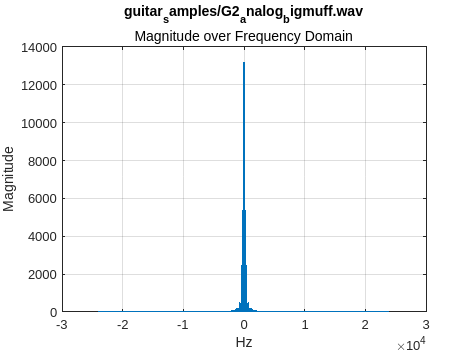

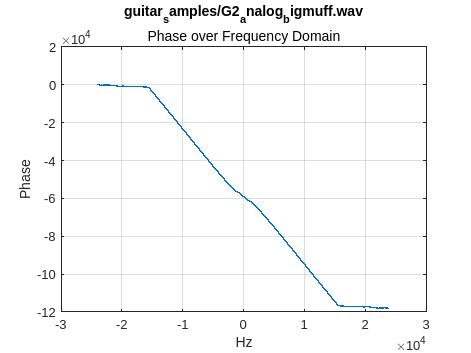

clear;
plotAudioFrequency('guitar_samples/G2_analog_bigmuff.wav');

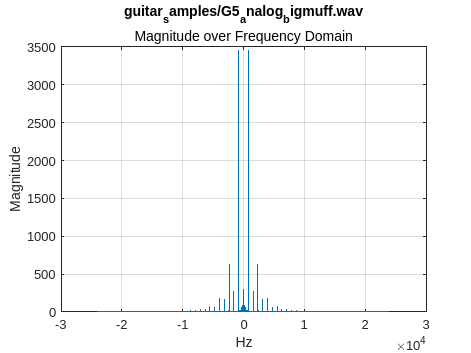

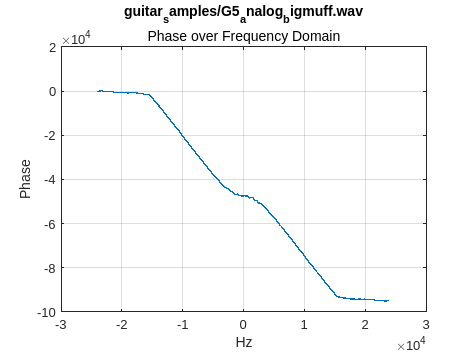

plotAudioFrequency('guitar_samples/G5_analog_bigmuff.wav');

function plotAudioFrequency(sample)
    % Read in the sound file
    [y, fs] = audioread(sample);

    % Take N-point FFT where N is the length of the signal
    ydft = fft(y);
    n = numel(y); % Get N - length of signal

    % Create frequency vector - make sure you remove last point
    freq = linspace(-fs/2, fs/2, n+1);
    freq(end) = [];

    % Shift the spectrum
    shiftSpectrum = fftshift(ydft);

    % Plot magnitude in frequency domain
    figure; 
    plot(freq, abs(shiftSpectrum)); 
    title(sample)
    subtitle(['Magnitude over Frequency Domain']); 
    xlabel('Hz'); 
    ylabel('Magnitude'); 
    %xlim([0, 3000])
    grid on; 

    % Plot phase in frequency domain
    figure; 
    plot(freq, unwrap(angle(shiftSpectrum))); 
    title(sample)
    subtitle(['Phase over Frequency Domain']); 
    xlabel('Hz'); 
    ylabel('Phase'); 
    grid on; 
end
